# Fuel Economy Analysis

This demo is an example of performing data mining on historical fuel economy data. We have data from various cars built from year 2000 up to 2012.

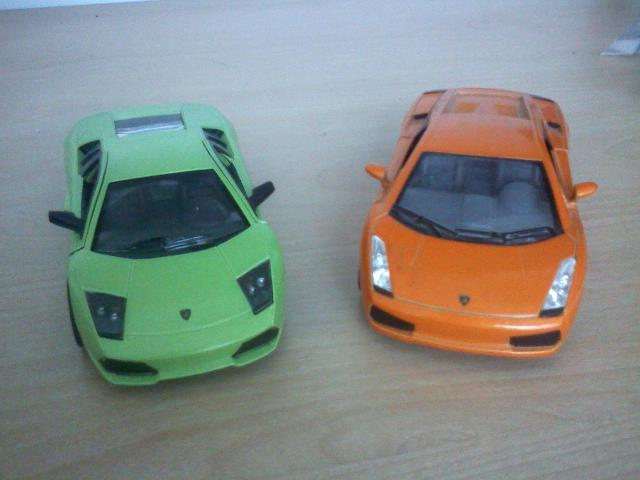

## Import Data into Table

Import from Excel using modified auto-generated function from Import Tool

carData = importYearXLS(2007);

Error using xlsread (line 136)
XLSREAD unable to open file 'dataXLS\2007dat.xlsx'.
File 'C:\Users\ahaciogl\Desktop\CSUN\MATLAB for Excel Users\fuel economy demo\dataXLS\2007dat.xlsx' not found.

Error in importYearXLS>importfile (line 71)
[~, ~, raw] = xlsread(workbookFile, sheetName, sprintf('A%d:X%d',startRow(1),endRow(1)));

Error in 

## Visualize

Plot MPG versus Rated Horsepower

createMPGFigure(carData.RatedHP, carData.MPG);

## Examine Grouping Effects of Categorical Data

In order to extract all "cars":


$$\$$


carIDs = carData.Car_Truck == "car";

In order to extract "city" data for "trucks":

city_truckIDs = (carData.City_Highway == "city" & carData.Car_Truck == "truck");

City versus Highway

cityIDs = carData.City_Highway == "city";
highwayIDs = carData.City_Highway == "highway";

## Grouped Visualizations

Scatter plot by group.

figure
gscatter(carData.RatedHP, carData.MPG, ...
    {carData.Car_Truck, carData.City_Highway}, ...
    '', '.', 10, 'on', 'Rated Horsepower', 'MPG')

## Extract Data for Curve Fitting

Create these variables for Curve Fitting App

RatedHPCity = carData.RatedHP(cityIDs);
MPGCity     = carData.MPG(cityIDs);

% Use the App to develop a curve fit.

## Curve Fitting

Equation:


$$\textrm{MPG}=b_1 +\frac{b_2 }{\textrm{RatedHP}}$$


We can solve this using the Curve Fitting Tool

`cftool(carData.RatedHP, carData.MPG)`

The following is a modified version of the auto-generated m-file from `cftool`.

cf = createMPGFit(carData.RatedHP, carData.MPG);

## Plot Data and Model

The result from the Curve Fitting Toolbox has a `plot` method for displaying the result graphically. We can choose to display the prediction bounds for the fit.

figure
hh = plot(cf, 'r', carData.RatedHP, carData.MPG, 'predobs', 0.95);
hh(2).LineWidth = 2;
for ii = [3 4]
    hh(ii).LineStyle = '-';
    hh(ii).Color = [0 0.5 0];
end

## Plot of Data and Model (for different groups)

We will apply the similar modeling technique to the data for different combinations of groups (Car-Truck and City-Highway)

Model different combinations:

[mdl,gof] = modelMPG(carData, 'car', 'city')
[mdl,gof] = modelMPG(carData, 'car', 'highway')
[mdl,gof] = modelMPG(carData, 'truck', 'city')
[mdl,gof] = modelMPG(carData, 'truck', 'highway')

*Copyright 2017 The MathWorks, Inc.*